# 1 Hail Impact on Insurance

The live-script is a complete, step-by-step MATLAB workflow that ingests radar-based hail intensities and insurance exposure/claim data, empirically calibrates and fits Emanuel-type PAA / MDR damage curves, benchmarks modelled losses against observations, and finally exports all calibrated impact functions and comparison tables.

We use the following randomized test data:

- **test_meshs.nc**: A hazard dataset with the same format as the used radar data (MESHS=Maximum expected severe hail size). Here with 1 month duration, small spatial extent, and 5 days with an artificial circular hail footprint.

- **test_exp.csv**: An exposure dataset with coordinates and building values with the same format as the data from building insurances in the publication. Here Simply random values on a regular grid.

- **test_dmg.csv**: A table of artificial observed hail damages. Here, including 4 rectangular patches of damages on 4 out of the 5 days with nonzero hazard intensity.

Note that the small number of (randomized) exposure and damage reports and the short consideredtime period of 1 month lead to high uncertainties and such a calibration would ****not**** be recommended with so little data.

## Step 1: Read Test Data and Existing Data from Python

projRoot = getProjRoot();            % project root directory

Data directory resolved to:
/Users/ray/Desktop/hail_damage_model_matlab


data_dir = fullfile(projRoot, 'out_files');
fprintf('Data directory resolved to:\n%s\n', data_dir);

Data directory resolved to:
/Users/ray/Desktop/hail_damage_model_matlab/out_files


files = { ...
  'hazard_intensity.csv'         'hazard';        ...
  'exposures.csv'                'exposures';     ...
  'observed_impacts.csv'         'obs_impacts';   ...
  'modelled_impacts.csv'         'mod_impacts';   ...
  'impact_comparison_by_event.csv','by_event';   ...
  'empirical_all.csv'            'empirical_all'; ...
  'empirical_rolling.csv'        'empirical_roll';...
  'final_impact_function.csv'    'impact_fn';     ...
  'bootstrap_MDR.csv'            'bootstrap_MDR'  ...
};

for i=1: size(files, 1)
    fname = files{i,1};
    varname = files{i,2};
    fullPath = fullfile(data_dir, fname);
    T = readtable(fullPath);
    assignin('base', varname, T);
    fprintf('Loaded %s → %s (%d×%d)\n', fname, varname, size(T));
end

Loaded hazard_intensity.csv → hazard (37696×6)
Loaded exposures.csv → exposures (3000×6)
Loaded observed_impacts.csv → obs_impacts (4×3)
Loaded modelled_impacts.csv → mod_impacts (31×3)
Loaded impact_comparison_by_event.csv → by_event (5×3)
Loaded empirical_all.csv → empirical_all (93×7)
Loaded empirical_rolling.csv → empirical_roll (81×11)
Loaded final_impact_function.csv → impact_fn (100×10)
Loaded bootstrap_MDR.csv → bootstrap_MDR (16200×3)


### Data Visualization

#### Hazard

intdir = fullfile(projRoot, 'test_data');
filename = fullfile(intdir, 'test_meshs.nc');
ncdisp(fullfile(intdir, 'test_meshs.nc'));

Source:
           /Users/ray/Desktop/hail_damage_model_matlab/test_data/test_meshs.nc
Format:
           netcdf4
Dimensions:
           time = 31
           chy  = 38
           chx  = 32
Variables:
    time
           Size:       31x1
           Dimensions: time
           Datatype:   int64
           Attributes:
                       units    = 'days since 2021-04-01'
                       calendar = 'proleptic_gregorian'
    lat 
           Size:       32x38
           Dimensions: chx,chy
           Datatype:   double
           Attributes:
                       _FillValue = NaN
                       units      = 'degrees_north'
    lon 
           Size:       32x38
           Dimensions: chx,chy
           Datatype:   double
           Attributes:
                       _FillValue = NaN
                       units      = 'degrees_east'
    chx 
           Size:       32x1
           Dimensions: chx
           Datatype:   int64
           Attributes:
                       axi

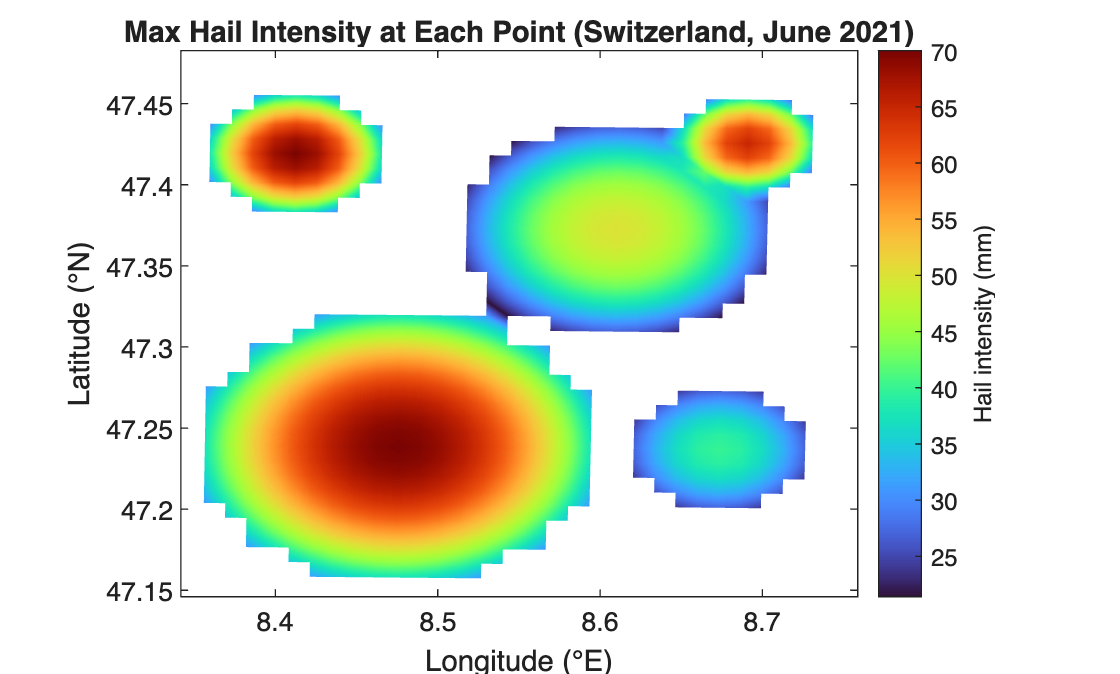

% Read 3D hail intensity (MZC)
intensity = ncread(filename, 'MZC');

% Compute max over time (3rd dimension)
max_intensity = max(intensity, [], 3);

% Read 2D lon/lat grids
lon = ncread(filename, 'lon');
lat = ncread(filename, 'lat');

% Transpose for correct orientation
max_intensity = max_intensity';
lon = lon';
lat = lat';

% Plot using imagesc or pcolor
figure;
pcolor(lon, lat, max_intensity);
shading interp;
axis equal tight;
xlabel('Longitude (°E)');
ylabel('Latitude (°N)');
title('Max Hail Intensity at Each Point (Switzerland, June 2021)');

% Colorbar
cb = colorbar;
cb.Label.String = 'Hail intensity (mm)';
colormap(turbo);

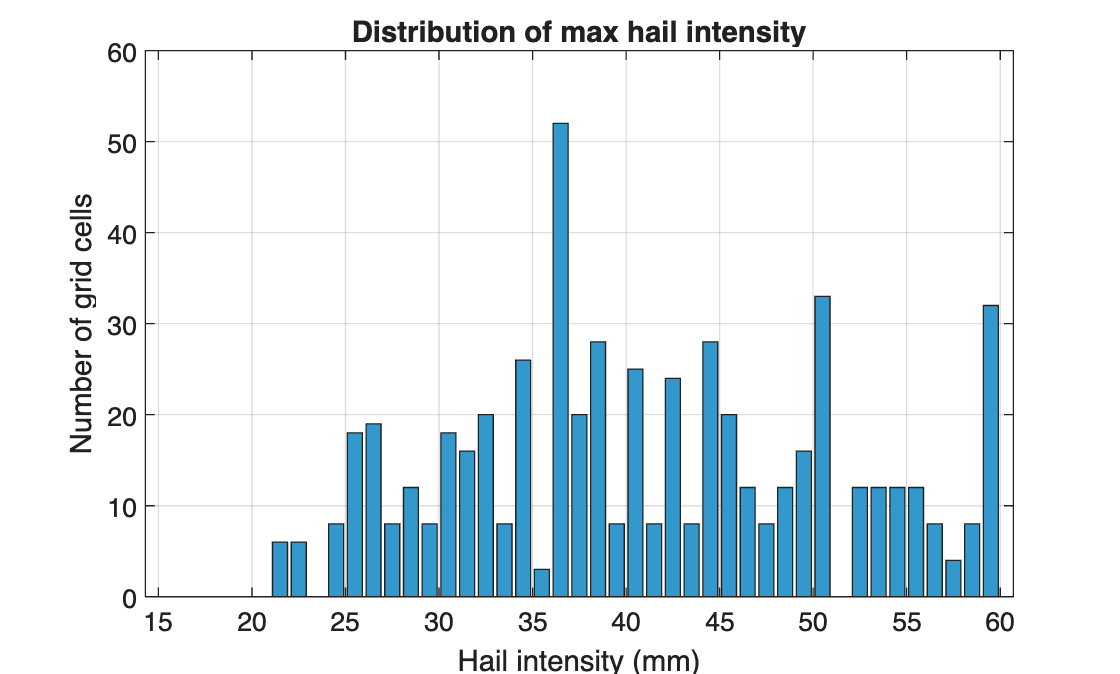

% Define bin edges (e.g., 0–60 mm in 5 mm steps)
bin_edges = 15:1:60;

% Flatten 2D matrix into vector and remove NaNs
vals = max_intensity(:);
vals = vals(~isnan(vals));

% Count number of grid cells per bin
counts = histcounts(vals, bin_edges);

% Use bin centers for plotting
bin_centers = bin_edges(1:end-1) + diff(bin_edges)/2;

% Create bar chart
figure;
bar(bin_centers, counts, 'FaceColor',[0.2 0.6 0.8]);
xlabel('Hail intensity (mm)');
ylabel('Number of grid cells');
title('Distribution of max hail intensity');
grid on;

#### Exposure

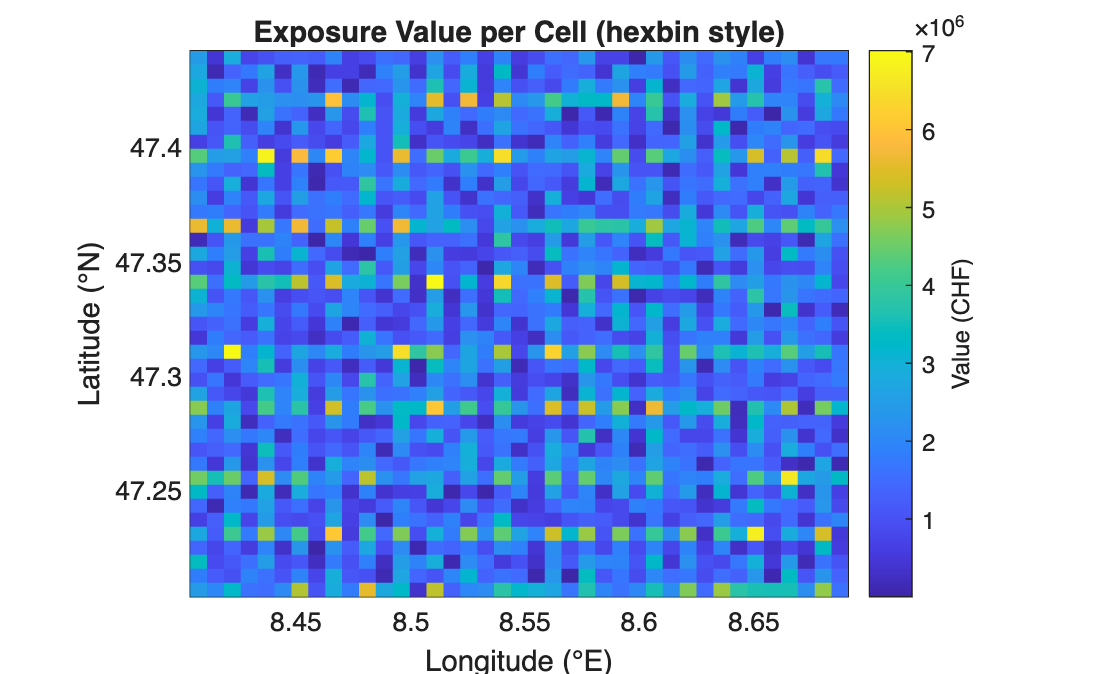

lonE = exposures.longitude;
latE = exposures.latitude;
valE = exposures.value;

% Build 40×40 bins
nbins  = 40;
xedges = linspace(min(lonE), max(lonE), nbins+1);
yedges = linspace(min(latE), max(latE), nbins+1);

[~,~,~,binX,binY] = histcounts2(lonE, latE, xedges, yedges);

% Sum value in each cell
sumVal = accumarray([binX(binX>0), binY(binY>0)], valE(binX>0), [nbins, nbins]);

% Compute bin‐centers
xcent = (xedges(1:end-1)+xedges(2:end))/2;
ycent = (yedges(1:end-1)+yedges(2:end))/2;

% Plot
figure;
h = pcolor(xcent, ycent, sumVal');
set(h,'EdgeColor','none');
shading flat;
axis equal tight;
xlabel('Longitude (°E)');
ylabel('Latitude (°N)');
title('Exposure Value per Cell (hexbin style)');
cb = colorbar;
cb.Label.String = 'Value (CHF)';

#### Damage

file = fullfile(projRoot, 'test_data', 'test_dmg.csv');
T    = readtable(file);

colLon  = "longitude";
colLat  = "latitude";
colLoss = "Schadensumme";
colDate = "date_dt";

% convert date column to datetime if it isn't yet
if ~isdatetime(T.(colDate))
    T.(colDate) = datetime(T.(colDate));
end

%% Spatial bubble plot (log-scaled bubbles)
figure('Name','Spatial distribution of claims','Color','w');
scatter(T.(colLon), T.(colLat), ...
        6 + 20*log10(T.(colLoss)), ...
        T.(colLoss), 'filled');
colorbar; colormap(turbo);
xlabel('Longitude'); ylabel('Latitude');
title('Hail-claim locations (bubble size ∝ loss)');
grid on

% Daily total damage time series
daily = groupsummary(T, colDate, 'sum', colLoss);
figure('Name','Daily total damage','Color','w');
bar(daily.(colDate), daily.("sum_"+colLoss)/1e6, 'FaceColor',[0.45 0.6 0.8]);
xlabel('Date'); ylabel('Total damage (million CHF)');
title('Daily hail loss totals');
grid on; box on

## Step 2: Perform Empirical Calibration

The script converts raw hazard and exposure tables into empirical PAA and MDR curves, fits a physically-interpretable sigmoid, and displays the resulting damage-probability relationship.

### Percentage of Asset Affected (PAA)

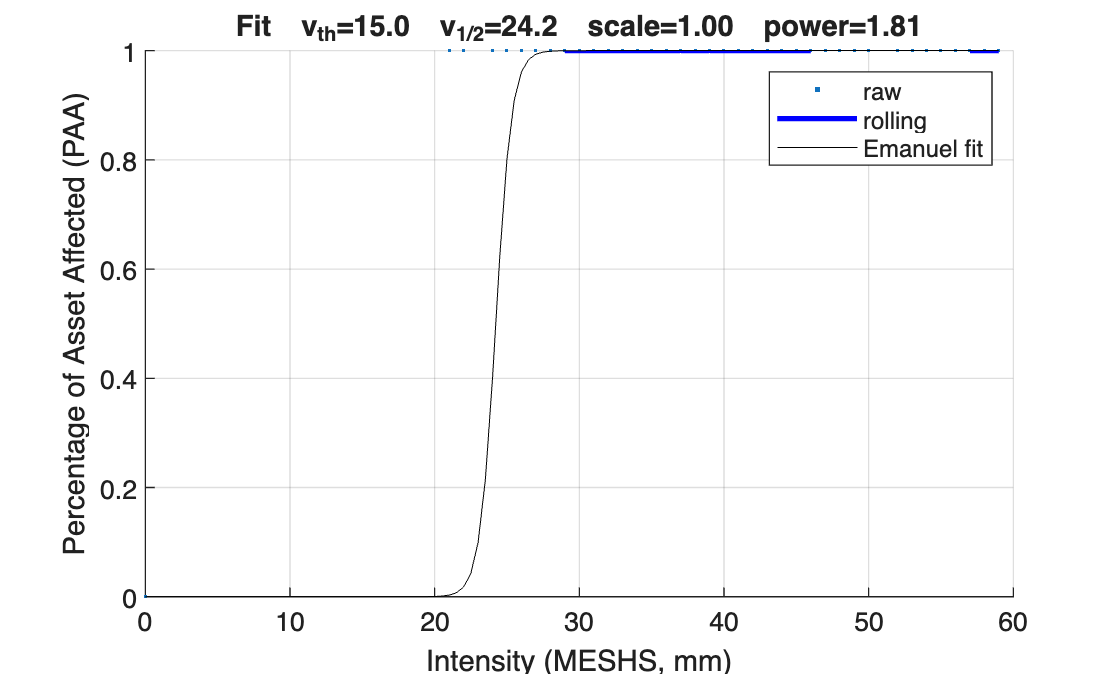

emanuel = @(p,I) (I >= p(1)) .* ( p(3) ./ ( 1 + exp( -p(4) .* (I - p(2)) ) ) );

% Load hazard grid  (long table: time, chy, chx, lat, lon, intensity)
T_haz = readtable(fullfile(data_dir,'hazard_intensity.csv'));
if ~isdatetime(T_haz.time);  T_haz.time = datetime(T_haz.time);  end
T_haz = T_haz(~isnan(T_haz.intensity), :);   % drop NaNs

% Collapse to **one scalar per grid node** (max MESHS over all times)
T_haz.lat_r = round(T_haz.lat, 4);
T_haz.lon_r = round(T_haz.lon, 4);
T_haz.key   = strcat(string(T_haz.lat_r),'|',string(T_haz.lon_r));
G = groupsummary(T_haz, 'key', 'max', 'intensity');
G.Properties.VariableNames{'max_intensity'} = 'Imax';
colLat = 'lat';
colLon = 'lon';

% Unique-sorted vectors (define before you call ismember)
latVec = unique( T_haz.(colLat) );
lonVec = unique( T_haz.(colLon) );

[~, iLat] = ismember( T_haz.(colLat), latVec );
[~, iLon] = ismember( T_haz.(colLon), lonVec );

%% Load exposure table and merge the max intensity
E = readtable(fullfile(data_dir,'exposures.csv'));
% Round to same 4-dec grid & build key
E.lat_r = round(E.latitude,4);
E.lon_r = round(E.longitude,4);
E.key   = strcat(string(E.lat_r),'|',string(E.lon_r));

% Join: adds Imax to every asset (outerjoin keeps all exposures)
E = outerjoin(E, G(:,{'key','Imax'}), 'Keys','key', 'MergeKeys',true);
E.intensity = E.Imax;
E.intensity(isnan(E.intensity)) = 0;

% Define a damage indicator at asset level
% You *only* have event-level losses in your CSV set, so as a placeholder
% we say an asset is "damaged" if its max MESHS ≥ 20 mm.  Adjust this rule
% or merge a claims file if you have one.
dmgThreshAsset = 20;
E.damaged = E.intensity >= dmgThreshAsset;

% Bin assets by intensity -> n_exp, n_dmgs, PAA
edges = 0:1:60;
nBins = numel(edges)-1;

[n_exp,~,binIdx] = histcounts(E.intensity, edges);
valid = binIdx > 0 & binIdx <= nBins;
n_dmgs = accumarray( binIdx(valid), double(E.damaged(valid)), ...
                     [nBins,1], @sum, 0 );

n_exp  = n_exp(:);
n_dmgs = n_dmgs(:);

PAA = n_dmgs ./ n_exp;

T_emp = table(edges(1:end-1)', n_exp, n_dmgs, PAA, ...
              'VariableNames', {'intensity','n_exp','n_dmgs','PAA'});

% Rolling (10-mm window)
win = 10;
T_roll = T_emp;
T_roll.PAA = movmean(T_emp.PAA, win, 'Endpoints','shrink');

% Fit Emanuel sigmoid  ——  keep only finite y
x = T_roll.intensity;
y = T_roll.PAA;

mask = isfinite(y);
xFit = x(mask);
yFit = y(mask);

p0 = [15, 35, max(yFit), 3];
lb = [0 10 0 1];      ub = [20 80 1 5];
opts = optimoptions('lsqcurvefit','Display','off');

pHat = lsqcurvefit(emanuel, p0, xFit, yFit, lb, ub, opts);

%% Plot empirical PAA + fit
figure('Name','PAA & Emanuel'), hold on
scatter(T_emp.intensity, T_emp.PAA, 6, '.','DisplayName','raw')
plot(x, y, 'b','LineWidth',2,'DisplayName','rolling')
xf = (min(x):0.5:max(x))';
plot(xf, emanuel(pHat,xf), 'k','LineWidth',0.1,'DisplayName','Emanuel fit')
xlabel('Intensity (MESHS, mm)'), ylabel('Percentage of Asset Affected (PAA)')
title(sprintf('Fit  v_{th}=%.1f  v_{1/2}=%.1f  scale=%.2f  power=%.2f',pHat))
legend show, grid on

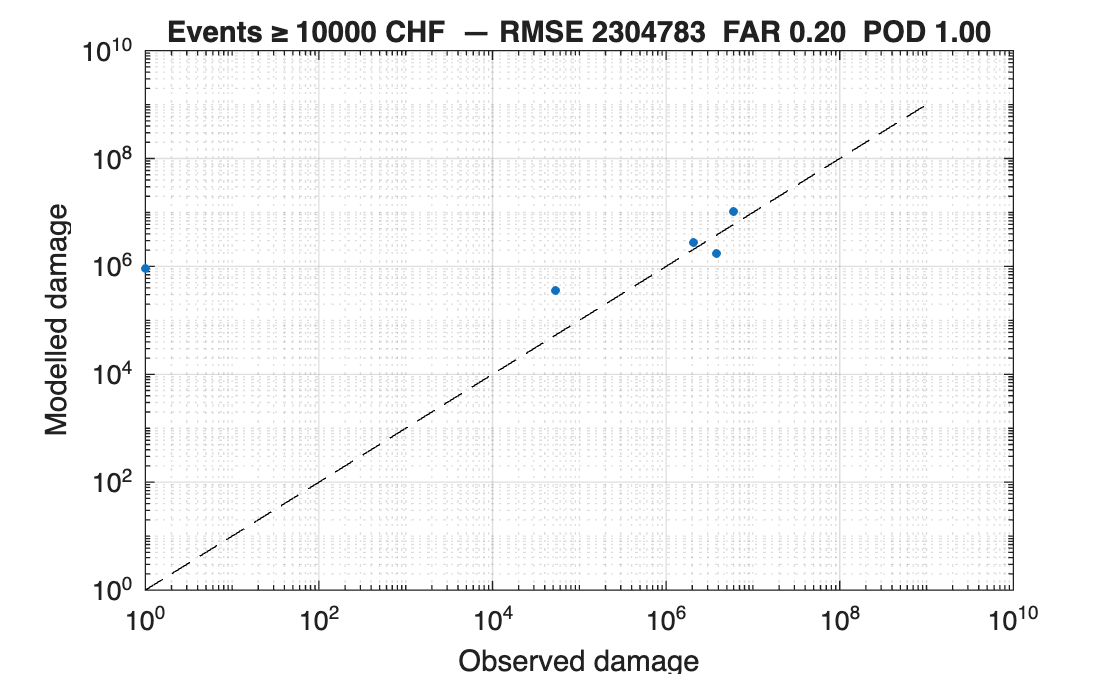

% Event-level skill scatter
impCSV = fullfile(data_dir,'impact_comparison_by_event.csv');

if isfile(impCSV)
    C = readtable(impCSV);
    colObs = 'imp_obs';
    colMod = 'imp_modelled';
    thresh = 1e4;
    mask   = C.imp_obs>thresh | C.imp_modelled>thresh;
    rmse = sqrt(mean( (C.imp_obs(mask)-C.imp_modelled(mask)).^2 ));
    fa   = C.imp_modelled>thresh & C.imp_obs<=thresh;
    hit  = C.imp_modelled>thresh & C.imp_obs >thresh;
    FAR  = sum(fa) /(sum(fa)+sum(hit));
    POD  = sum(hit)/(sum(hit) + sum(C.imp_obs<=thresh & C.imp_modelled<=thresh));

    figure('Name','Event scatter'), loglog(C.(colObs)+1, C.(colMod)+1, '.', 'MarkerSize', 10)
    hold on, plot([1 1e9],[1 1e9],'k--')
    xlabel('Observed damage'), ylabel('Modelled damage')
    title(sprintf('Events ≥ %.0f CHF  — RMSE %.0f  FAR %.2f  POD %.2f', ...
                  thresh, rmse, FAR, POD))
    grid on
end

### Mean Damage Ratio (MDR)

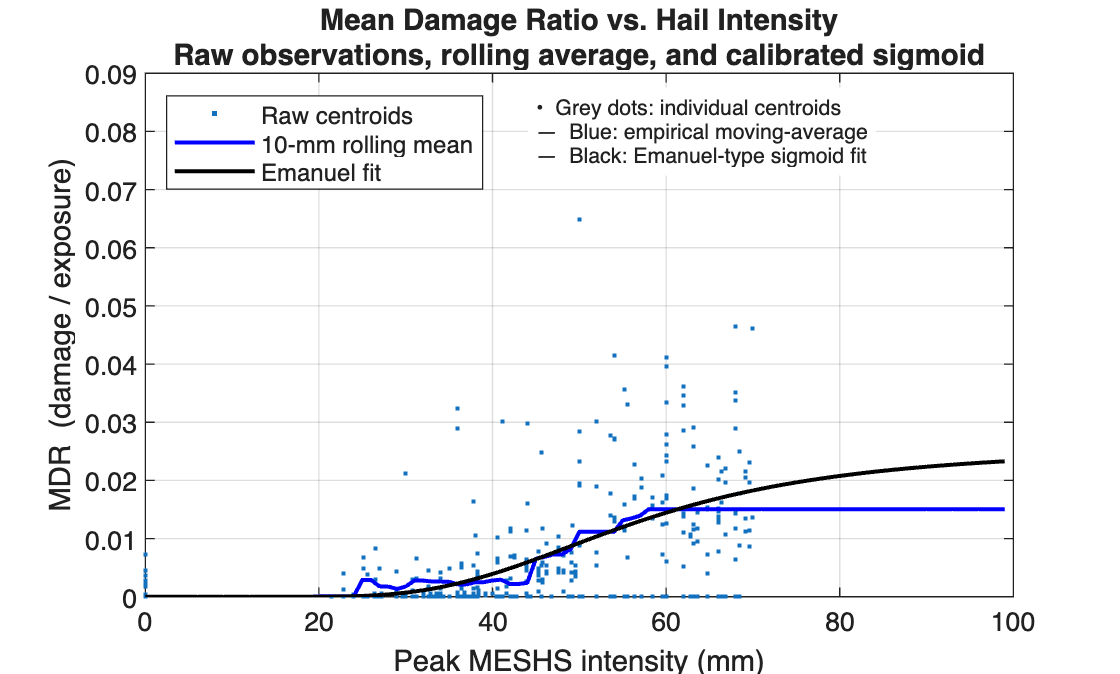

tempdir = fullfile(projRoot, 'test_data', 'temp');
T_cent  = readtable(fullfile(tempdir,'at_centr.csv'));      % per–centroid data
T_impf  = readtable(fullfile(tempdir,'test_impf.csv'));     % impact-function table

figure('Color','w'); hold on

%% 1)  Raw centroid-level MDR points
scatter(T_cent.MESHS, T_cent.MDR, 16, '.', ...
        'DisplayName','Raw centroids');

%% 2)  Rolling / smoothed empirical curve
plot(T_impf.Var1, T_impf.MDR, ...
     'b', 'LineWidth',1.5, ...
     'DisplayName','10-mm rolling mean');

%% 3)  Calibrated Emanuel sigmoid
plot(T_impf.Var1, T_impf.MDR_emanuel, ...
     'k', 'LineWidth',1.5, ...
     'DisplayName','Emanuel fit');

%% 4)  Axes styling, title, legend, annotation
grid on; box on
xlabel('Peak MESHS intensity (mm)');
ylabel('MDR  (damage / exposure)');
title({'Mean Damage Ratio vs. Hail Intensity', ...
       'Raw observations, rolling average, and calibrated sigmoid'});

legend('Location','northwest');

% Optional explanatory text inside the plot
text(45, 0.08,               ...    % adjust coords as needed
    {'•  Grey dots: individual centroids', ...
     '—  Blue: empirical moving-average', ...
     '—  Black: Emanuel-type sigmoid fit'}, ...
    'FontSize',8, 'BackgroundColor','w');

### Calibration Summary Graph

vars   = {'PAA','MDR','MDD'};
cmap   = lines(numel(vars));

figure('Name','Impact curves: PAA / MDR / MDD');  clf;  hold on

for k = 1:numel(vars)
    y = 100 * T_impf.(vars{k});
    plot(T_impf.Var1, y, ...
         'LineWidth', 2, 'Color', cmap(k,:), ...
         'DisplayName', vars{k});
end

xlabel('Intensity (MESHS, mm)')
ylabel('Impact (% of insured value / assets)')
title('Rolling impact curves calibrated from centroids')
legend('Location','NorthWest')
grid on
hold off

#### Smoothened Graph

vars   = {'PAA','MDR','MDD'};             % metrics to show
cRoll  = lines(numel(vars));              % colours for rolling
cSmoo  = cRoll .* 0.5 + 0.5;              % lighter shade for smooth

figure('Name','Rolling vs. Smoothed curves'); clf; hold on

for k = 1:numel(vars)
    v  = vars{k};
    x  = T_impf.Var1;

    % rolling
    y_roll = 100 * T_impf.(v);
    plot(x, y_roll, 'Color', cRoll(k,:), 'LineWidth', 1.8, ...
         'DisplayName', [v ' rolling']);

    % smooth version provided by scClim (preserves monotonicity)
    colSmooth = [v '_smooth'];
    if ismember(colSmooth, T_impf.Properties.VariableNames)
        y_smooth = 100 * T_impf.(colSmooth);
        plot(x, y_smooth, '--', 'Color', cSmoo(k,:), 'LineWidth', 1.5, ...
             'DisplayName', [v ' smooth']);
    else
        warning('Column %s not found in test_impf.csv', colSmooth)
    end
end

xlabel('Intensity (MESHS, mm)')
ylabel('Impact  (% of insured value / assets)')
title('Rolling (solid) vs. Smooth (dashed) impact curves')
legend('Location','NorthWest')
grid on
hold off

Compare among different smoothen method with interactive view

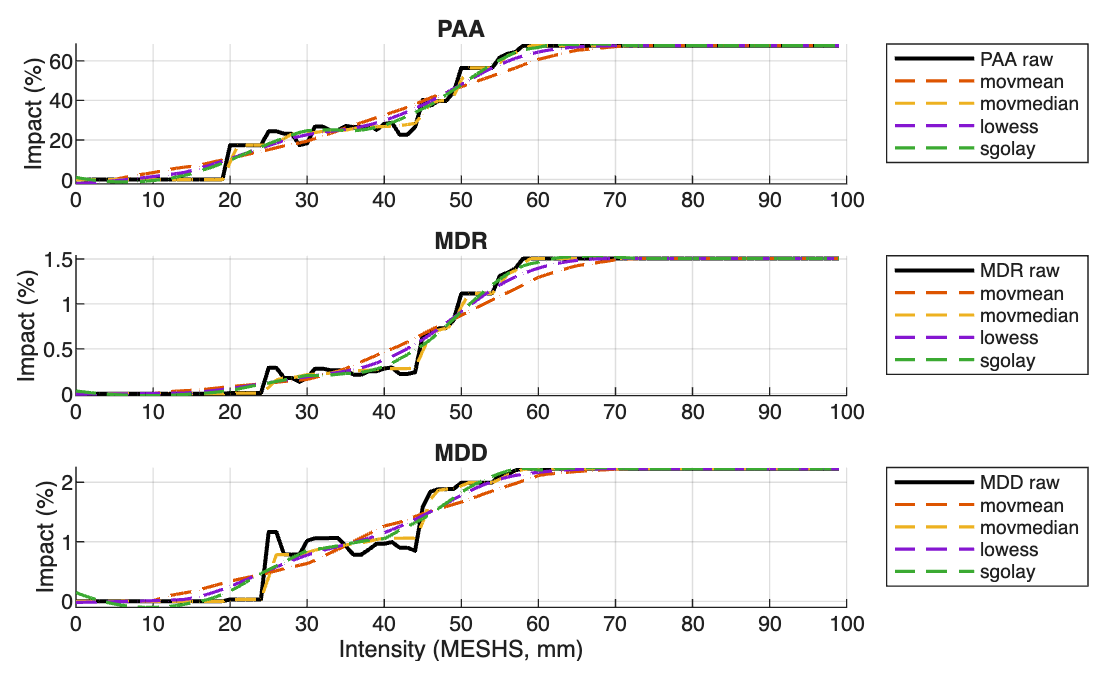

smooth_methods = {'movmean','movmedian','lowess','sgolay'};
winSize = 30;

vars = {'PAA','MDR','MDD'};
x = T_impf.Var1;

% Setup figure and layout
figure('Name','Different smoothing methods'); clf;
tiledlayout(numel(vars), 1, 'Padding','compact', 'TileSpacing','compact');

for k = 1:numel(vars)
    v = vars{k};
    y = T_impf.(v);

    nexttile;
    hold on;
    plot(x, 100*y, 'k-', 'LineWidth', 1.5, 'DisplayName', [v ' raw']);

    for m = 1:numel(smooth_methods)
        method = smooth_methods{m};

        if isnumeric(y)
            y_smooth = smoothdata(y, method, winSize);
            plot(x, 100*y_smooth, '--', 'LineWidth', 1.2, ...
                'DisplayName', method);
        end
    end

    title(v, 'Interpreter', 'none');
    ylabel('Impact (%)');
    legend('Location','northeastoutside');
    grid on;
end

xlabel('Intensity (MESHS, mm)');

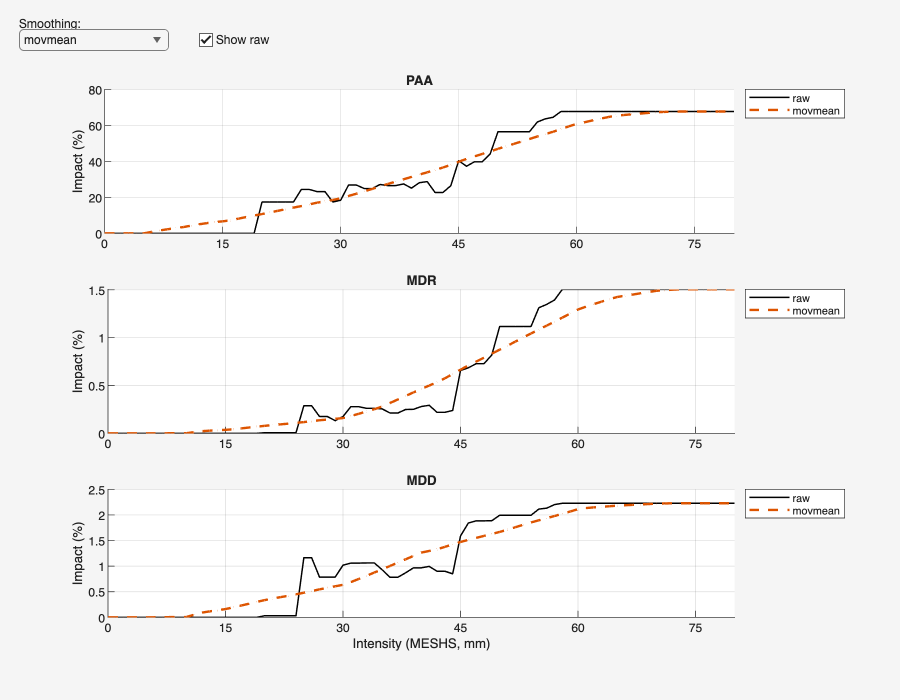

function demoSmoothingDashboard(T_impf)
% Interactive plot with drop-down for smoothing method
smoothMethods = {'movmean','movmedian','lowess','sgolay'};
winSize       = 30;
vars          = {'PAA','MDR','MDD'};
x             = T_impf.Var1;

% ----------------------------------------------------
% 1. UI figure & controls
% ----------------------------------------------------
f = uifigure('Name','Smoothing demo','Position',[100 100 900 700]);

lbl = uilabel(f,'Text','Smoothing:', ...
              'Position',[20 670 70 15]);

dd  = uidropdown(f, ...
      'Items',smoothMethods, ...
      'Position',[20 650 150 22], ...
      'Value',smoothMethods{1});

cb  = uicheckbox(f, ...
      'Text','Show raw', ...
      'Value',true, ...
      'Position',[200 650 100 22]);

% axes grid (manual, because tiledlayout doesn't work under uifigure)
nVar = numel(vars);
ax   = gobjects(nVar,1);
for k = 1:nVar
    ax(k) = uiaxes(f,'Position',[70 450-(k-1)*200 780 180]);
    hold(ax(k),'on')
end

% 2. Initial draw
plotAll()

% ----------------------------------------------------
% 3. Callbacks
% ----------------------------------------------------
dd.ValueChangedFcn = @(~,~) plotAll();
cb.ValueChangedFcn = @(~,~) plotAll();

% ----------------------------------------------------
% nested helper to redraw the three panels
% ----------------------------------------------------
    function plotAll
        method  = dd.Value;
        showRaw = cb.Value;
        for j = 1:nVar
            v = vars{j};  y = T_impf.(v);
            cla(ax(j)); hold(ax(j),'on')
            
            if showRaw
                plot(ax(j),x,100*y,'k-','LineWidth',1.1,...
                     'DisplayName','raw');
            end
            
            yS = smoothdata(y,method,winSize);
            plot(ax(j),x,100*yS,'--','LineWidth',1.8,...
                 'DisplayName',method);
            
            title(ax(j),v,'Interpreter','none')
            ylabel(ax(j),'Impact (%)')
            grid(ax(j),'on')
            legend(ax(j),'Location','northeastoutside')
            ax(j).XLim  = [0 80];
            ax(j).XTick = 0:15:80;
        end
        xlabel(ax(end),'Intensity (MESHS, mm)')
    end
end


demoSmoothingDashboard(T_impf);

## Step 3: Compare Different R**egression Learners for PAA / MDR / MDD**

% Data: 1-D feature (Var1)  →  three targets (PAA, MDR, MDD)
tbl = T_impf(:,{'Var1','PAA','MDR','MDD'});
tbl.Var1 = double(tbl.Var1);      % insure numeric

% One hold-out split so *every* learner is tested on identical data
cvp      = cvpartition(height(tbl),'HoldOut',0.2);
trainTbl = tbl(training(cvp),:);
testTbl  = tbl(test(cvp),   :);

Xtrain = trainTbl.Var1;
Xtest  = testTbl.Var1;

% Helper – tiny wrapper so fitr* functions get a 1-column table
toTbl = @(x) table(x,'VariableNames',{'Var1'});

% Learner library  (final fit  |  5-fold CV fit)
k = 5;
learners = { ...
  'Linear (ridge)', ...
      @(x,y) fitrlinear(toTbl(x),y, ...
                        'Learner','leastsquares','Regularization','ridge'), ...
      @(x,y) fitrlinear(toTbl(x),y, ...
                        'Learner','leastsquares','Regularization','ridge', ...
                        'KFold',k); ...

  'Low-order Spline', ...
      @(x,y) fitrgam(toTbl(x),y,'Interactions',0), ...
      @(x,y) fitrgam(toTbl(x),y,'Interactions',0,'CrossVal','on','KFold',k); ...

  'GPR  (SE)', ...
      @(x,y) fitrgp(toTbl(x),y,'Basis','none','KernelFunction','squaredexponential'), ...
      @(x,y) fitrgp(toTbl(x),y,'Basis','none','KernelFunction','squaredexponential', ...
                   'KFold',k); ...

  'Bagged Trees', ...
      @(x,y) fitrensemble(toTbl(x),y,'Method','Bag','NumLearningCycles',200), ...
      @(x,y) fitrensemble(toTbl(x),y,'Method','Bag','NumLearningCycles',200, ...
                          'KFold',k); ...

  'Boosted Trees', ...
      @(x,y) fitrensemble(toTbl(x),y,'Method','LSBoost', ...
                          'NumLearningCycles',400,'LearnRate',0.05), ...
      @(x,y) fitrensemble(toTbl(x),y,'Method','LSBoost', ...
                          'NumLearningCycles',400,'LearnRate',0.05, ...
                          'KFold',k); ...
  };


targets = {'PAA','MDR','MDD'};

% Fit, cross-validate, and score
results = table();

for t = 1:numel(targets)
    yTr = trainTbl.(targets{t});
    yTe = testTbl.(targets{t});

    for L = 1:size(learners,1)
        name   = learners{L,1};
        fitFun = learners{L,2};
        cvFun  = learners{L,3};

        mdl   = fitFun(Xtrain, yTr);   % final, no CV
        cvMdl = cvFun(Xtrain, yTr);    % 5-fold CrossValidatedRegressionModel

        yHatCV = kfoldPredict(cvMdl);
        yHatTe = predict(mdl, toTbl(Xtest));
        % compute performance metrics
        RMSE_test = sqrt(mean((yHatTe - yTe).^2));
        MAE_test  = mean(abs(yHatTe - yTe));
        R2_test   = 1 - sum((yHatTe - yTe).^2) / sum((yTe - mean(yTe)).^2);
        RMSE_cv   = sqrt(mean((yHatCV - yTr).^2));

        % append a row to the results table
        results = [results;
                   {targets{t}, name, RMSE_test, MAE_test, R2_test, RMSE_cv}];
    end
end

results.Properties.VariableNames = ...
    {'Target','Model','RMSE_Test','MAE_Test','R2_Test','RMSE_CV'};

results = sortrows(results,{'Target','RMSE_Test'});
disp(results);

    Target            Model            RMSE_Test      MAE_Test     R2_Test     RMSE_CV  
    _______    ____________________    __________    __________    _______    __________

    {'MDD'}    {'Low-order Spline'}    0.00035078    0.00015958     0.9985     0.0016549
    {'MDD'}    {'Boosted Trees'   }    0.00043291    0.00019684    0.99771     0.0015048
    {'MDD'}    {'Bagged Trees'    }    0.00052333    0.00031274    0.99666     0.0012505
    {'MDD'}    {'GPR  (SE)'       }     0.0017074      0.001198    0.96445     0.0021811
    {'MDD'}    {'Linear (ridge)'  }     0.0033438     0.0028514    0.86366     0.0037722
    {'MDR'}    {'GPR  (SE)'       }    0.00054475    0.00035531    0.99248     0.0007159
    {'MDR'}    {'Low-order Spline'}      0.000687    0.00033203    0.98804    0.000

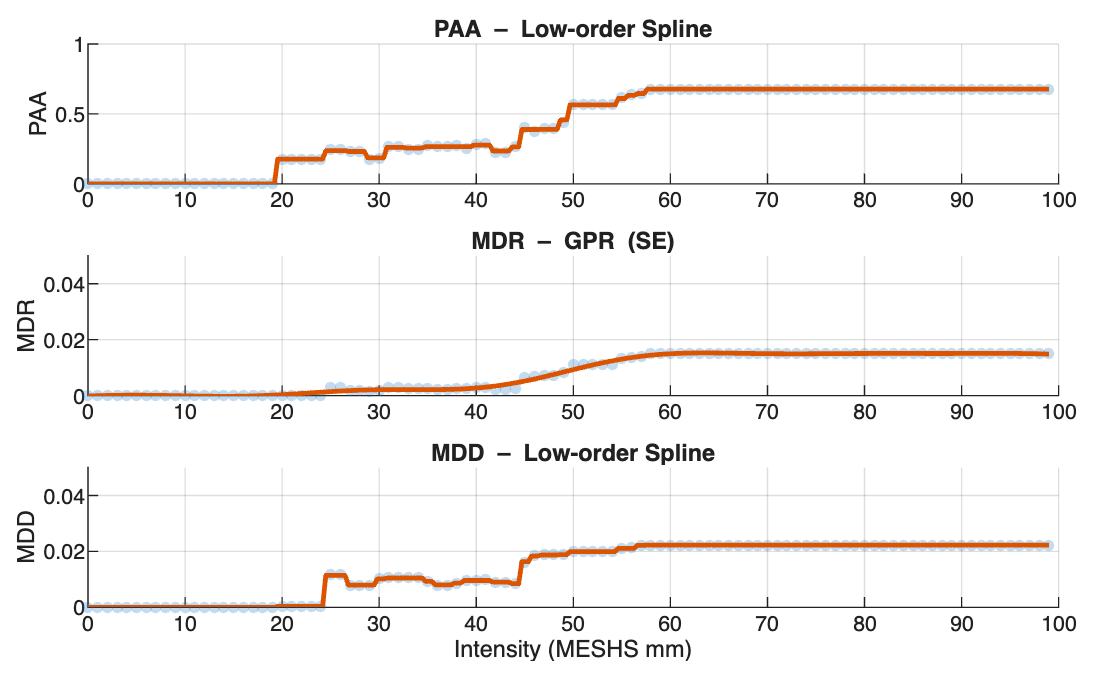

% Visualise the best model for each target
% – PAA: y-axis 0–1
% – MDR & MDD: y-axis 0–0.1
figure('Name','Best fits per target');
tiledlayout(3,1,'Padding','compact','TileSpacing','compact')

for kT = 1:numel(targets)
    T      = targets{kT};
    subTab = results(strcmp(results.Target,T),:);
    [~,i]  = min(subTab.RMSE_Test);
    name   = subTab.Model{i};

    fitFun = learners{strcmp(learners(:,1),name), 2};
    mdl    = fitFun(tbl.Var1, tbl.(T));

    xx = linspace(min(tbl.Var1), max(tbl.Var1), 300)';
    yy = predict(mdl, toTbl(xx));

    hAx = nexttile;                         % axis handle
    hold(hAx,'on')
    scatter(hAx, tbl.Var1, tbl.(T), 18, 'filled', 'MarkerFaceAlpha',0.25)
    plot  (hAx, xx, yy, 'LineWidth',1.8)

    % per-target limits
    if strcmp(T,'PAA')
        set(hAx,'YLim',[0 1])
    else           % MDR or MDD
        set(hAx,'YLim',[0 0.05])
    end
    set(hAx,'YLimMode','manual')            % lock it

    grid(hAx,'on')
    title(hAx, sprintf('%s  –  %s', T, name))
    ylabel(hAx, T)
end
xlabel('Intensity (MESHS mm)')

### Extension: Higher Dimensional Surface and Neural Network

To enrich the modelling dataset I refine the spatial grid from 0.05 ° to 0.01 ° (~1 km), map every hazard pixel, exposure record, and claim to its new cell ID, and aggregate cell-level features. The code above produces, for every 0.01 ° cell, the mean hail intensity (`hazardMean`), total insured value and policy count (`exposure`,`Nexp`), total paid loss and damaged-asset count (`damage`,`Ndmg`), plus the derived responses:

**PAA** (= `Ndmg/Nexp`), and

**MDR** (= `damage/exposure`). 

With many more cells the sample size increases substantially, giving a richer 3-D dataset ⟨intensity, exposure, location⟩ → {PAA, MDR}. These denser observations enable higher-dimensional surface fitting or machine-learning methods (GAM, GPR, neural nets) to capture non-linear interactions and should yield more accurate, exposure-sensitive impact functions compared with the coarser grid used earlier.

#### Raw Surface

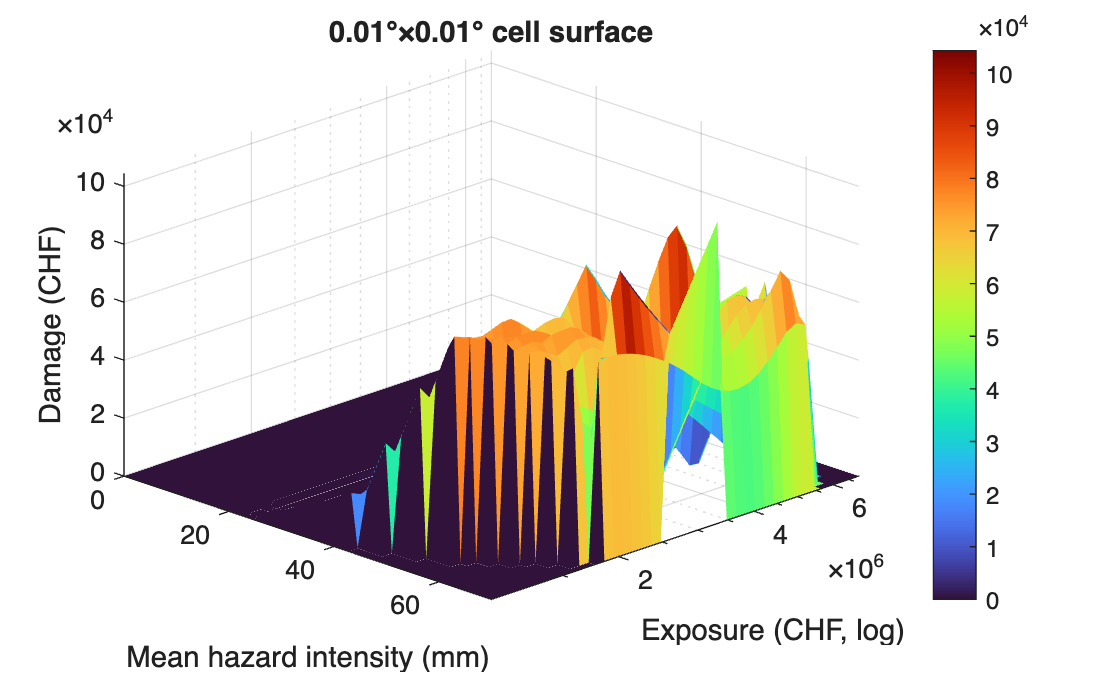

%  FILES  +  COLUMN NAMES
hazFile  = data_dir + "/hazard_intensity.csv";
expFile  = data_dir + "/exposures.csv";
dmgFile  = fullfile(projRoot, 'test_data', 'test_dmg.csv');

if ismember('lon', T_haz.Properties.VariableNames)
    T_haz.Properties.VariableNames{'lon'} = 'longitude';
end
if ismember('lat', T_haz.Properties.VariableNames)
    T_haz.Properties.VariableNames{'lat'} = 'latitude';
end

colLat   = "latitude";
colLon   = "longitude";
colExpo  = "value";            % exposure in exposures.csv
colLoss  = "Schadensumme";    % loss   in test_dmg.csv
colHazT  = "time";             % datetime in hazard_intensity.csv
colDmgT  = "date_dt";          % datetime in claims.csv

tolDays  = days(1);            % ±1-day claim window
gridLon = unique(T_haz.(colLon));
gridLat = unique(T_haz.(colLat));
snap = @(v,g) g( knnsearch(g, v) );

%  LOAD
T_haz = readtable(hazFile);  T_haz.(colHazT)=datetime(T_haz.(colHazT));
T_haz.(colHazT) = datetime(T_haz.(colHazT));
T_haz.latitude  = T_haz.lat;          % overwrite / create latitude
T_haz.longitude = T_haz.lon;          % overwrite / create longitude
T_haz(:,{'lat','lon'}) = [];         % remove the temp columns

E     = readtable(expFile);
T_dmg = readtable(dmgFile);  T_dmg.(colDmgT)=datetime(T_dmg.(colDmgT));

cellLonSize = 0.01;      % 0.01°  grid resolution
cellLatSize = 0.01;      % 0.01°  north–south
cellCol = @(lo) floor( (lo - min(gridLon)) / cellLonSize );
cellRow = @(la) floor( (la - min(gridLat)) / cellLatSize );

% hazards
T_haz.cCol = cellCol( T_haz.(colLon) );
T_haz.cRow = cellRow( T_haz.(colLat) );
T_haz.cell = T_haz.cCol * 1e5 + T_haz.cRow;   % unique scalar ID

% exposures
E.cCol = cellCol( E.(colLon) );
E.cRow = cellRow( E.(colLat) );
E.cell = E.cCol * 1e5 + E.cRow;

% claims
T_dmg.cCol = cellCol( T_dmg.(colLon) );
T_dmg.cRow = cellRow( T_dmg.(colLat) );
T_dmg.cell = T_dmg.cCol * 1e5 + T_dmg.cRow;

ExpoCell = groupsummary(E,'cell','sum',colExpo);
ExpoCell = renamevars(ExpoCell,"sum_"+colExpo,'exposure');

LossCell = groupsummary(T_dmg,'cell','sum',colLoss);
LossCell = renamevars(LossCell,"sum_"+colLoss,'damage');

HazCell  = groupsummary(T_haz,'cell','mean','intensity');
HazCell  = renamevars(HazCell,'mean_intensity','hazardMean');

C = outerjoin(ExpoCell,HazCell,'Keys','cell','MergeKeys',true);
C = outerjoin(C,       LossCell,'Keys','cell','MergeKeys',true);

C.exposure(isnan(C.exposure))     = 0;
C.hazardMean(isnan(C.hazardMean)) = 0;
C.damage(isnan(C.damage))         = 0;

% recover integer col/row then centroid coordinates
C.cCol = floor(double(C.cell) / 1e5);
C.cRow = mod( double(C.cell), 1e5);

C.lon  = min(gridLon) + (C.cCol + 0.5)*cellLonSize;
C.lat  = min(gridLat) + (C.cRow + 0.5)*cellLatSize;

C = C(:,{'cell','lon','lat','exposure','hazardMean','damage'});
C = C(C.hazardMean > 0 , :); 

% plot
x = C.hazardMean;
y = C.exposure;
z = C.damage;

mask = isfinite(x)&isfinite(y)&isfinite(z)&y>0;
x=x(mask); y=y(mask); z=z(mask);

% coarse grid in intensity & exposure
xg = linspace(0,max(x),60);
yg = logspace(log10(min(y)),log10(max(y)),40);
[Xg,Yg] = meshgrid(xg,yg);

F  = scatteredInterpolant(x,log10(y),z,'natural','none');
Zg = F(Xg,log10(Yg));  Zg(isnan(Zg))=0;

figure('Name','Macro-cell damage surface','Color','w');
surf(Xg,Yg,Zg,'EdgeColor','none'); set(gca,'YScale','log');
xlabel('Mean hazard intensity (mm)');
ylabel('Exposure (CHF, log)');
zlabel('Damage (CHF)');
title(sprintf('%.2f°×%.2f° cell surface',cellLonSize,cellLatSize));
view(45,30); colormap(turbo); colorbar; axis tight

#### Prepare the grid and necessary data

for T = {T_haz,E,T_dmg}
    if ismember('lon', T{1}.Properties.VariableNames)
        T{1}.Properties.VariableNames{'lon'} = colLon;
    end
    if ismember('lat', T{1}.Properties.VariableNames)
        T{1}.Properties.VariableNames{'lat'} = colLat;
    end
end
[T_haz,E,T_dmg] = deal(T_haz,E,T_dmg);

%% Define grid origin
minLon = min([T_haz.(colLon); E.(colLon); T_dmg.(colLon)]);
minLat = min([T_haz.(colLat); E.(colLat); T_dmg.(colLat)]);

cellCol = @(lon)  floor( (lon - minLon) / cellLonSize );
cellRow = @(lat)  floor( (lat - minLat) / cellLatSize );
cellID  = @(cCol,cRow) cCol*100000 + cRow;       % unique scalar key

%% Assign every row to a cell
T_haz.cCol = cellCol( T_haz.(colLon) );          T_haz.cRow = cellRow( T_haz.(colLat) );
E.    cCol = cellCol( E.(colLon)     );          E.    cRow = cellRow( E.(colLat)     );
T_dmg.cCol = cellCol( T_dmg.(colLon) );          T_dmg.cRow = cellRow( T_dmg.(colLat) );

T_haz.cell = cellID(T_haz.cCol,T_haz.cRow);
E.    cell = cellID(E.    cCol,E.    cRow);
T_dmg.cell = cellID(T_dmg.cCol,T_dmg.cRow);

%% Aggregate per 0.01° cell
% Hazard: mean intensity
HazCell  = groupsummary(T_haz,'cell','mean','intensity');
HazCell  = renamevars(HazCell,'mean_intensity','hazardMean');

% Exposure: total CHF + record count = Nexp
ExpoCell = groupsummary(E,'cell','sum',colExpo);      % GroupCount auto-added
ExpoCell = renamevars(ExpoCell, ...
             ["sum_"+colExpo,"GroupCount"], ["exposure","Nexp"]);

% Damage values: total CHF in rows with positive loss
maskPos  = T_dmg.(colLoss) > 0;
LossVal  = groupsummary(T_dmg(maskPos,:),'cell','sum',colLoss);
LossVal  = renamevars(LossVal,"sum_"+colLoss,'damage');

% Damage counts: how many assets damaged = Ndmg
if any(maskPos)
    LossCnt = groupsummary(T_dmg(maskPos,:), 'cell', 'sum', colLoss);
    LossCnt = renamevars(LossCnt,'GroupCount','Ndmg');
else
    LossCnt = table([], [], 'VariableNames', {'cell','Ndmg'});
end

%% Combine all four subtables
C = outerjoin(HazCell, ExpoCell, 'Keys','cell', 'MergeKeys',true);
C = outerjoin(C,       LossVal,  'Keys','cell', 'MergeKeys',true);
C = outerjoin(C,       LossCnt,  'Keys','cell', 'MergeKeys',true);

% replace NaNs with 0 where appropriate
for v = ["hazardMean","exposure","damage","Nexp","Ndmg"]
    C.(v)(isnan(C.(v))) = 0;
end

%% Compute PAA & MDR
C.PAA = NaN(height(C),1);                     % avoid 0/0 → NaN
C.PAA(C.Nexp > 0)      = C.Ndmg(C.Nexp>0)    ./ C.Nexp(C.Nexp>0);

C.MDR = NaN(height(C),1);
C.MDR(C.exposure > 0)  = C.damage(C.exposure>0) ./ C.exposure(C.exposure>0);

%% Recover grid centroids (lon/lat)
C.cCol = floor(double(C.cell)/1e5);
C.cRow = mod(double(C.cell),1e5);
C.lon  = minLon + (C.cCol + 0.5)*cellLonSize;
C.lat  = minLat + (C.cRow + 0.5)*cellLatSize;

%% Quick sanity printout
fprintf('Cells with exposure>0   : %d\n', sum(C.exposure > 0));

Cells with exposure>0   : 775


fprintf('Cells with Ndmg>0       : %d\n', sum(C.Ndmg     > 0));

Cells with Ndmg>0       : 309


fprintf('Global PAA (all cells)  : %.3f\n', nansum(C.Ndmg)/nansum(C.Nexp));

Global PAA (all cells)  : 0.357


fprintf('Global MDR (all cells)  : %.3f\n', nansum(C.damage)/nansum(C.exposure));

Global MDR (all cells)  : 0.004


#### Set up the model matrix

mask =  C.exposure  > 0  &  C.hazardMean > 0;

D = table( ...
      C.hazardMean(mask) , ...                  % predictor 1
      log10(C.exposure(mask)) , ...             % predictor 2 (log-scale)
      C.PAA(mask) , ...                         % target 1
      C.MDR(mask) , ...                         % target 2
      'VariableNames',{'intensity','logExpo','PAA','MDR'});

% main effects + interaction term
kFolds = 10;
cv     = cvpartition(height(D), 'KFold', kFolds);

deviance = zeros(kFolds,1);

% for numeric safety when we take log(ŷ)
clip = @(p) max(min(p, 1-1e-12), 1e-12);

#### GLM

for k = 1:kFolds
    tr = training(cv,k);          % logical index for training rows
    te = test(cv,k);              % logical index for test rows
    
    % fit the GLM on the kth training split
    mdlK = fitglm( D(tr,:), ...
        'PAA ~ intensity + logExpo + intensity:logExpo', ...
        'Distribution','binomial','Link','logit');
    
    % predict on the held-out split
    yhat = clip( predict(mdlK, D(te,:)) );
    y    = D.PAA(te);
    
    % binomial deviance for this fold
    deviance(k) = -2*sum( y .* log(yhat) + (1-y).*log(1-yhat) );
end

cvDev = mean(deviance);
fprintf('10-fold CV deviance  =  %.3f\n', cvDev);

10-fold CV deviance  =  57.134


mdlP = fitglm(D, ...
        'PAA ~ intensity + logExpo + intensity:logExpo', ...
        'Distribution','binomial', 'Link','logit');
fprintf('--- PAA GLM ---\n');  disp(mdlP);

--- PAA GLM ---

Generalized linear regression model:
    logit(PAA) ~ 1 + intensity*logExpo
    Distribution = Binomial

Estimated Coefficients:
                         Estimate        SE        tStat     pValue 
                         _________    ________    _______    _______

    (Intercept)            -22.778      16.784    -1.3572    0.17473
    intensity              0.52876      0.3607     1.4659    0.14267
    logExpo                 3.0497      2.5533     1.1944    0.23231
    intensity:logExpo    -0.071726    0.054905    -1.3064    0.19143


451 observations, 447 error degrees of freedom
Dispersion: 1
Chi^2-statistic vs. constant model: 60.1, p-value = 5.48e-13


#### Different models and fit

% predictors & response
X = D{:, {'intensity','logExpo'}};

#### Lasso-penalised logistic for PAA(Binary)

% Response: 1 if at least one damaged asset in the cell
yBin = (C.Ndmg(mask) > 0);          % logical 0/1

% Standardise predictors
[Xs,~,~] = zscore(X);

mdlLasso = fitclinear(Xs, yBin, ...
        'Learner','logistic', ...
        'Regularization','lasso', ...
        'KFold',10);

auc = 1 - kfoldLoss(mdlLasso, 'LossFun','classiferror');   % misclass error → 1-error ≈ pseudo-AUC
fprintf('Lasso logistic (binary) 10-fold score = %.3f\n', auc);

Lasso logistic (binary) 10-fold score = 0.639



[~,scores] = kfoldPredict(mdlLasso);     % scores(:,2) = P(class==1)

% 2.  True binary labels in the same order
y = yBin;                                % your 0/1 vector (size n×1)

% 3.  Binomial deviance
epsVal = 1e-12;                          % numeric guard
p = max(min(scores(:,2), 1-epsVal), epsVal);  % clip to (eps,1-eps)

dev = -2 * sum( y .* log(p) + (1-y) .* log(1-p) );

fprintf('Lasso-logistic 10-fold binomial deviance = %.1f\n', dev);

Lasso-logistic 10-fold binomial deviance = 579.4


#### Spline GAM for MDR

gamCV = fitrgam(D, 'MDR', ...
        'PredictorNames', {'intensity','logExpo'}, ...
        'Interactions',   'all', ...       % <-- accept both 1-D and 2-D smooths
        'Weights',        D.logExpo, ...
        'CrossVal',       'on');           % 10-fold CV

rmse = sqrt(kfoldLoss(gamCV,'LossFun','mse'));
fprintf('GAM 10-fold CV RMSE = %.4f\n', rmse);

GAM 10-fold CV RMSE = 0.0083



%% --- 1-D sigmoid functional form ---------------------------------------
sigFun = @(p,I) ( (max(I-p(1),0)./(p(2)-p(1))).^3 ./ ...
                 (1 + (max(I-p(1),0)./(p(2)-p(1))).^3 ) ) * p(3);  
% p = [v_thresh , v_half , scale] ; power fixed at 3

% starting guesses & bounds  (adjust if needed)
p0 = [  5 , median(D.intensity) , 0.02 ];   % start
lb = [  0 ,  min(D.intensity)  , 0       ]; % lower
ub = [ 20 ,  max(D.intensity)  , 0.50    ]; % upper

%% --- 10-fold cross-validation ------------------------------------------
cv     = cvpartition(height(D),'KFold',10);
rmseCv = zeros(cv.NumTestSets,1);

opts = optimoptions('lsqcurvefit','Display','off');

for k = 1:cv.NumTestSets
    tr = training(cv,k);  te = test(cv,k);

    % ----- fit sigmoid on training fold
    Ik = D.intensity(tr);
    Mk = D.MDR(tr);
    pk = lsqcurvefit(sigFun, p0, Ik, Mk, lb, ub, opts);

    % ----- predict on test fold
    yhat = sigFun(pk, D.intensity(te));
    err  = D.MDR(te) - yhat;
    rmseCv(k) = sqrt( mean(err.^2) );
end

sigmoidRMSE = mean(rmseCv);
fprintf('1-D sigmoid (intensity only) 10-fold CV RMSE = %.4f\n', sigmoidRMSE);

1-D sigmoid (intensity only) 10-fold CV RMSE = 0.0083


#### Lasso-penalised Bayesian-flavoured fit

% predictors (standardised)
X  = D{:, {'intensity','logExpo'}};
X  = [X, X(:,1).*X(:,2)];
[Xs,mu,sig] = zscore(X);

% response = proportion damaged
yProp   = C.Ndmg(mask) ./ C.Nexp(mask);   % PAA  (values in [0,1])
wTrials = C.Nexp(mask);                   % binomial sample size

[B,FitInfo] = lassoglm(Xs, yProp, 'binomial', ...
                       'Link', 'logit', ...
                       'Weights', wTrials, ...
                       'Alpha', 1, ...        % 1 = lasso
                       'CV', 10);             % 10-fold CV

% Pick λ at 1-standard-error rule (more shrinkage, stabler)
idx   = FitInfo.Index1SE;
coef  = [FitInfo.Intercept(idx);  B(:,idx)];
dev   = FitInfo.Deviance(idx);

fprintf('Lasso-GLM 10-fold deviance (1-SE λ) = %.3f\n', dev);

Lasso-GLM 10-fold deviance (1-SE λ) = 2047.718


sigmoid = @(z) 1./(1+exp(-z));

PAAhat = @(intens,expo) sigmoid( ...
        coef(1) + ...
        coef(2)*((intens-mu(1))./sig(1)) + ...
        coef(3)*((log10(expo)-mu(2))./sig(2)) + ...
        coef(4)*(((intens-mu(1))./sig(1)).*((log10(expo)-mu(2))./sig(2))) );

% example: probability at 35 mm hail & CHF 1 e6 exposure
PAAhat(35, 1e6)

ans = 0.4911

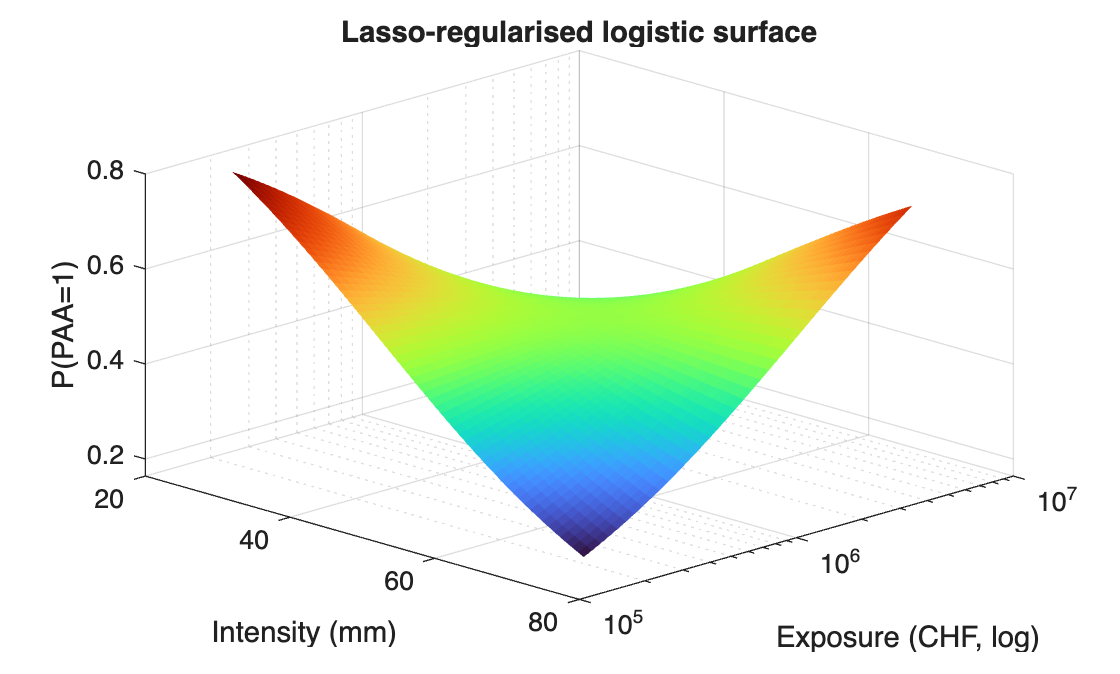

[Xi, Yi] = meshgrid(linspace(min(D.intensity),max(D.intensity),60), ...
                    logspace(log10(min(C.exposure(C.exposure>0))), ...
                             log10(max(C.exposure)),40));
Z   = PAAhat(Xi, Yi);

surf(Xi, Yi, Z,'EdgeColor','none'); set(gca,'YScale','log');
xlabel('Intensity (mm)'); ylabel('Exposure (CHF, log)'); zlabel('P(PAA=1)');
title('Lasso-regularised logistic surface'); view(45,30); colormap(turbo);

#### Neural Network - PAA

% Build predictor matrix X and target vectors  (hazard + log-exposure)
mask = C.exposure  > 0  &  C.hazardMean > 0;     % keep usable rows

Xraw = [ C.hazardMean(mask), ...
         log10(C.exposure(mask)) ]';             % 2 × N  (transpose)

yP = C.PAA(mask)';                               % 1 × N  binary target
yM = C.MDR(mask)';                               % 1 × N  regression target

% z-score each predictor (row-wise)
[X,mu,sig] = zscore(Xraw,0,2);

% reproducible 70 / 15 / 15 split
rng default
[tr,val,te] = dividerand(size(X,2),0.70,0.15,0.15);

netP = patternnet([8 4]);              % two hidden layers
netP.divideFcn = 'divideind';
netP.divideParam.trainInd = tr;
netP.divideParam.valInd   = val;
netP.divideParam.testInd  = te;
netP.trainParam.showWindow = false;

netP = train(netP,X,yP);
normX   = @(haz,expo) [(haz - mu(1))./sig(1) ;          % 2×1 column
                       (log10(expo) - mu(2))./sig(2)];
PAA_nn  = @(haz,expo) netP( normX(haz,expo) );          % scalar prob

% Quick check: should return a number between 0 and 1
fprintf('Test PAA_nn(35 mm, 1e6 CHF) = %.3f\n', PAA_nn(35,1e6));

Test PAA_nn(35 mm, 1e6 CHF) = 0.233


% test metrics
scoreP = netP(X(:,te));                         % 1×N vector of probabilities
[~,~,~,auc] = perfcurve(yP(te), scoreP, 1);     % AUC in the 4th output
fprintf('PAA NN – test AUC = %.3f\n', auc);

PAA NN – test AUC = 0.726


***Empirical PAA surface  (intensity × exposure)***

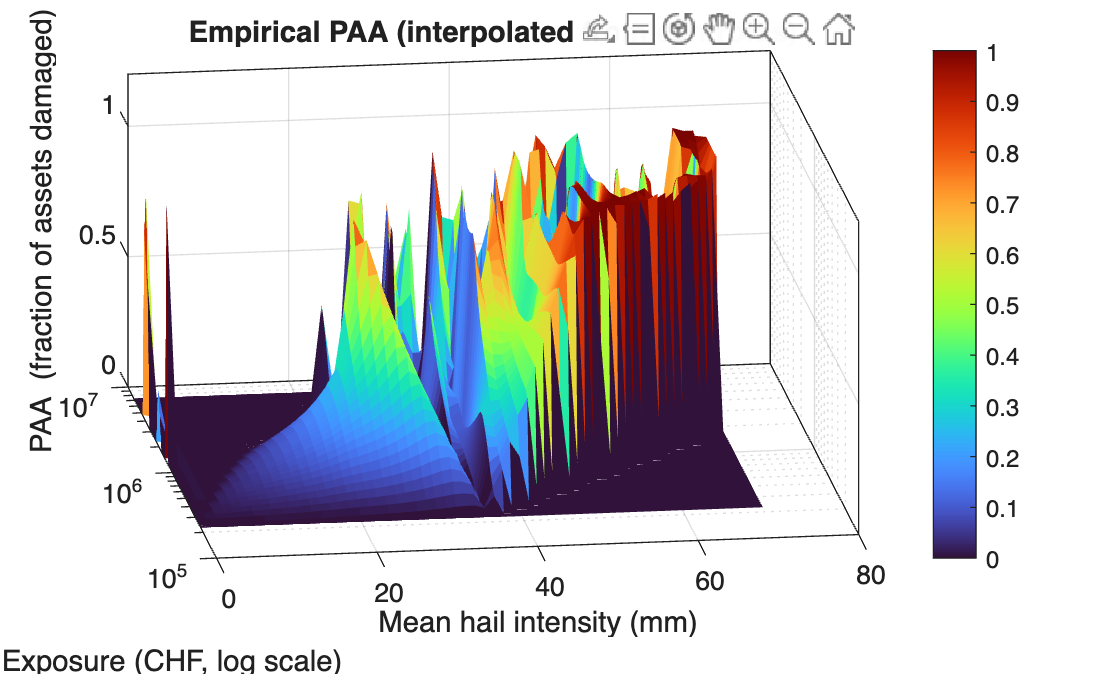

mask =  isfinite(C.hazardMean) & isfinite(C.exposure) & C.exposure>0 ...
      & isfinite(C.PAA);

x = C.hazardMean(mask);                    % intensity  (mm)
y = log10(C.exposure(mask));               % log₁₀ exposure (CHF)
p = C.PAA(mask);                           % raw PAA

% Regular grid
xg = linspace(min(x), max(x), 60);
yg = linspace(min(y), max(y), 40);
[Xg,Yg] = meshgrid(xg, yg);

% Natural‐neighbour interpolation
Fp = scatteredInterpolant(x,y,p,'natural','none');
Pg = Fp(Xg,Yg);  Pg(isnan(Pg)) = 0;        % fill outside-hull gaps with 0

% Plot
figure('Name','Empirical PAA surface','Color','w');
surf(Xg, 10.^Yg, Pg, 'EdgeColor','none');
set(gca,'YScale','log');
xlabel('Mean hail intensity (mm)');
ylabel('Exposure (CHF, log scale)');
zlabel('PAA  (fraction of assets damaged)');
title('Empirical PAA (interpolated from centroids)');
view(45,30); colormap(turbo); colorbar; grid on; box on;

***Neural Network PAA surface  (intensity × exposure)***

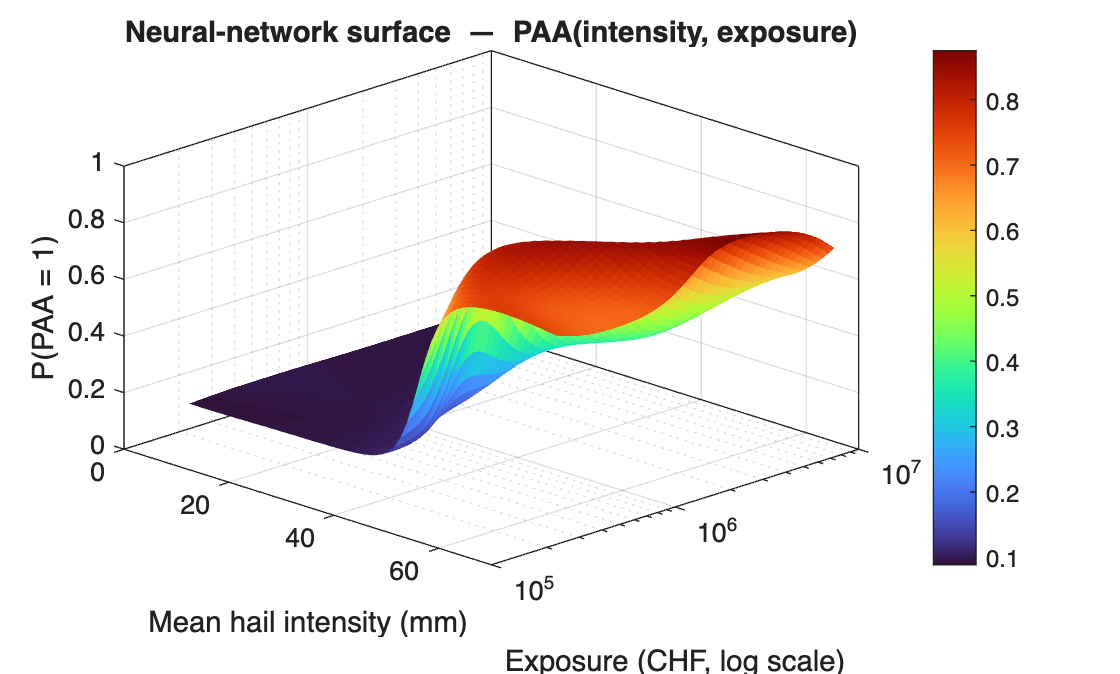

% Grid resolution
nI = 60;                      % intensity points
nE = 50;                      % exposure points

% Intensity and exposure ranges
Ivec = linspace(min(C.hazardMean(mask)), max(C.hazardMean(mask)), nI);          % mm
Evec = logspace(log10(min(C.exposure (mask))), log10(max(C.exposure(mask))), nE); % CHF

% Meshgrid and evaluate
[II, EE] = meshgrid(Ivec, Evec);
Psurf    = arrayfun(@(i,e) PAA_nn(i,e), II, EE);   % nE × nI probabilities

% Plot
figure('Name','Neural-net PAA surface','Color','w');
surf(II, EE, Psurf, 'EdgeColor','none');
set(gca,'YScale','log');                     % exposure axis on log scale
xlabel('Mean hail intensity (mm)');
ylabel('Exposure (CHF, log scale)');
zlabel('P(PAA = 1)');
title('Neural-network surface  —  PAA(intensity, exposure)');
colormap(turbo); colorbar;
view(45,30); grid on; box on;

***Line Charter PAA vs Intensity at Exposure: CHF 1,000,000***

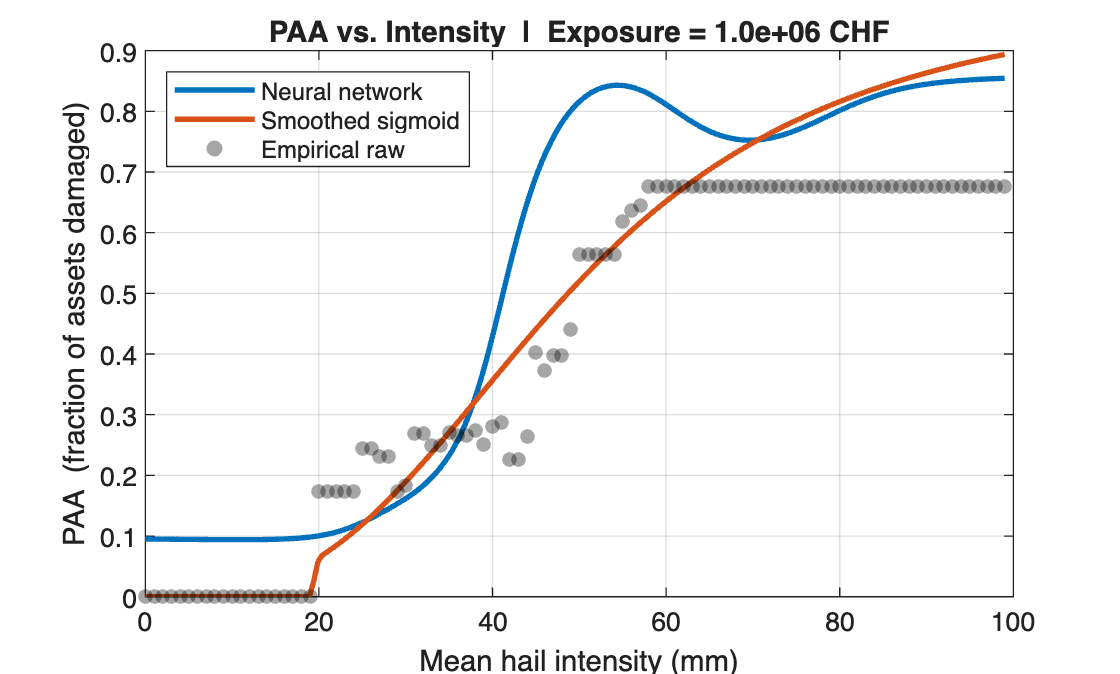

% Exposure slice
expoSlice = 1e6; % CHF 1 000 000

% Intensity grid
Igrid = linspace(min(T_impf.Var1), max(T_impf.Var1), 200);

% Neural-network PAA slice
P_nn  = arrayfun(@(I) PAA_nn(I, expoSlice), Igrid);

% Smoothed sigmoid (Emanuel) from table
P_sig = interp1(T_impf.Var1, T_impf.PAA_emanuel, Igrid, ...
                'linear','extrap');

% Raw empirical PAA points
I_raw = T_impf.Var1;
P_raw = T_impf.PAA;                     % unsmoothed empirical values

% Plot all three
figure('Color','w'); hold on

plot(Igrid, P_nn , 'LineWidth',2, 'Color',[0 0.447 0.741]);      % neural net
plot(Igrid, P_sig, 'LineWidth',2, 'Color',[0.850 0.325 0.098]);  % sigmoid
scatter(I_raw, P_raw, 30, 'k', 'filled', ...
        'MarkerFaceAlpha',0.35,'DisplayName','Empirical raw');   % raw data

grid on; box on
xlabel('Mean hail intensity (mm)');
ylabel('PAA  (fraction of assets damaged)');
title(sprintf('PAA vs. Intensity  |  Exposure = %.1e CHF', expoSlice));
legend({'Neural network','Smoothed sigmoid','Empirical raw'}, ...
       'Location','northwest');
hold off

#### Neural Network - MDR

% hidden layers: 8 and 4 units
netM = fitnet([8 4],'trainlm');
netM.divideFcn            = 'divideind';
netM.divideParam.trainInd = tr;
netM.divideParam.valInd   = val;
netM.divideParam.testInd  = te;
netM.trainParam.showWindow = false;

netM = train(netM, X, yM);

% Test-set evaluation
idxTest = find(te);                 % numeric indices, 1-based
yhat    = netM(X(:,idxTest));       % predictions
ytrue   = yM(idxTest);              % ground truth

rmse = sqrt( mean( (yhat - ytrue).^2 ) );
mae  = mean( abs( yhat - ytrue ) );

sst  = sum( (ytrue - mean(ytrue)).^2 );          % total SS about the mean
r2   = 1 - sum( (yhat - ytrue).^2 ) / sst;        % coefficient of determination

fprintf('MDR NN – test RMSE = %.4f\n', rmse);

MDR NN – test RMSE = 0.0132


fprintf('MDR NN – test MAE  = %.4f\n', mae );

MDR NN – test MAE  = 0.0101


fprintf('MDR NN – test R²   = %.3f\n', r2  );

MDR NN – test R²   = 0.220



%%  Convenience prediction handle
normX  = @(haz,expo) [(haz - mu(1))./sig(1) ; ...
                      (log10(expo) - mu(2))./sig(2)];
MDR_nn = @(haz,expo) netM( normX(haz,expo) );

***Empirical MDR surface  (intensity × exposure)***

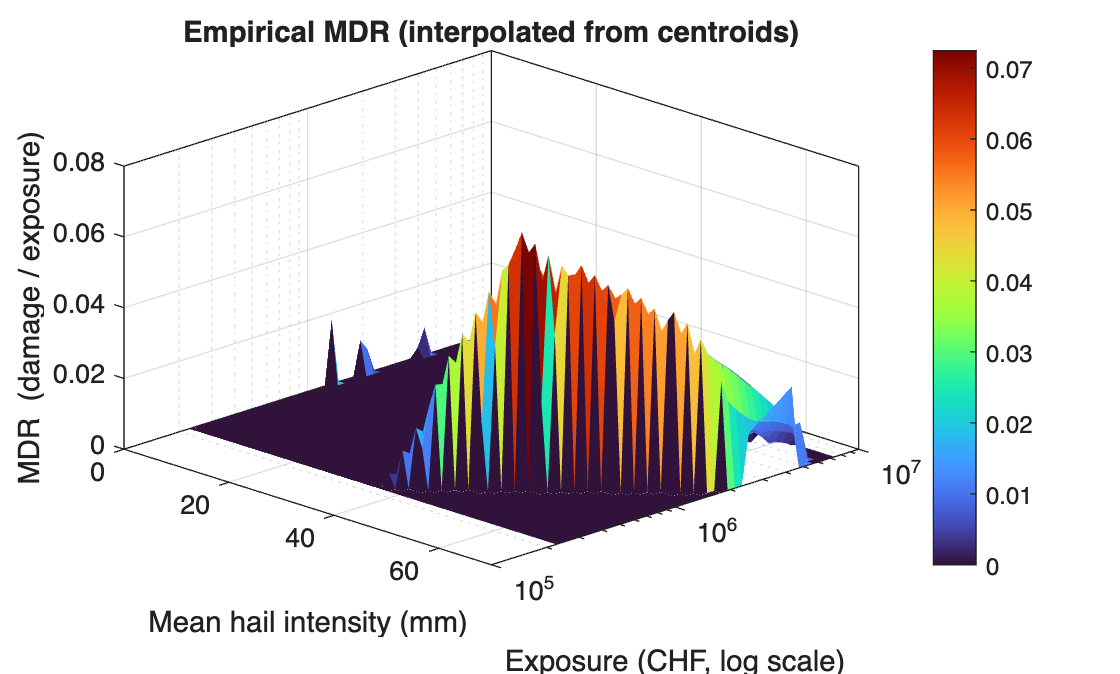

mask =  isfinite(C.hazardMean) & isfinite(C.exposure) & C.exposure>0 ...
      & isfinite(C.MDR);

x = C.hazardMean(mask);                    % intensity  (mm)
y = log10(C.exposure(mask));               % log₁₀ exposure (CHF)
m = C.MDR(mask);                           % raw MDR

% Regular grid
xg = linspace(min(x), max(x), 60);
yg = linspace(min(y), max(y), 40);
[Xg,Yg] = meshgrid(xg, yg);

% Natural‐neighbour interpolation
Fm = scatteredInterpolant(x,y,m,'natural','none');
Mg = Fm(Xg,Yg);  Mg(isnan(Mg)) = 0;

% Plot
figure('Name','Empirical MDR surface','Color','w');
surf(Xg, 10.^Yg, Mg, 'EdgeColor','none');
set(gca,'YScale','log');
xlabel('Mean hail intensity (mm)');
ylabel('Exposure (CHF, log scale)');
zlabel('MDR  (damage / exposure)');
title('Empirical MDR (interpolated from centroids)');
view(45,30); colormap(turbo); colorbar; grid on; box on;

***Neural Network MDR surface  (intensity × exposure)***

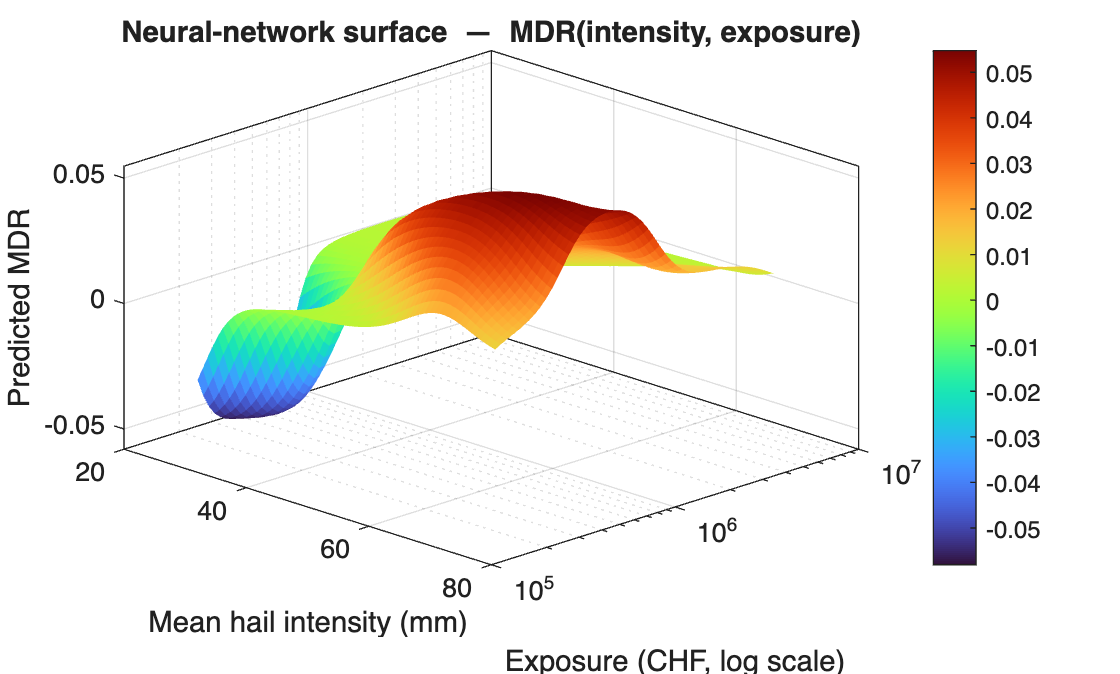

nX = 60;                              % grid points in intensity
nY = 50;                              % grid points in exposure
Ivec = linspace(min(D.intensity), max(D.intensity), nX);      % mm
Evec = logspace(log10(min(C.exposure(C.exposure>0))), ...
                log10(max(C.exposure)), nY);                  % CHF

[IX, EX] = meshgrid(Ivec, Evec);      % 2-D predictor grid
% Evaluate the NN on every grid point
Z = arrayfun(@(i,e) MDR_nn(i,e), IX, EX);    % nY × nX matrix

%% Plot
figure('Name','Neural-net MDR surface','Color','w');
surf(IX, EX, Z, 'EdgeColor','none');
set(gca,'YScale','log');              % log axis for exposure
xlabel('Mean hail intensity (mm)');
ylabel('Exposure (CHF, log scale)');
zlabel('Predicted MDR');
title('Neural-network surface  —  MDR(intensity, exposure)');
colormap(turbo); colorbar; view(45,30); grid on; box on;

***Line Charter MDR vs Intensity at Exposure: CHF 1,000,000***

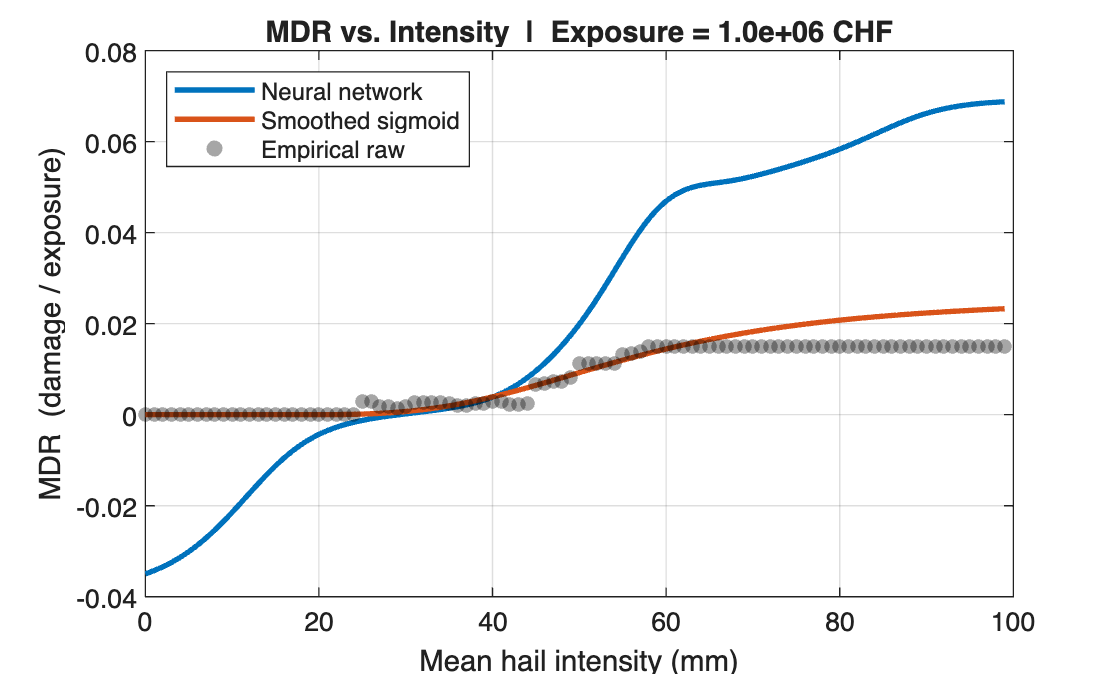

% Exposure slice (choose any exposure level)
expoSlice = 1e6; % CHF 1 000 000

% Intensity grid
Igrid = linspace(min(T_impf.Var1), max(T_impf.Var1), 200);

% Neural-network MDR slice
M_nn  = arrayfun(@(I) MDR_nn(I, expoSlice), Igrid);       % 1×200

% Smoothed sigmoid (Emanuel) from table
M_sig = interp1(T_impf.Var1, T_impf.MDR_emanuel, Igrid, ...
                'linear','extrap');

% Raw empirical points  (one dot per intensity bin)
I_raw = T_impf.Var1;
M_raw = T_impf.MDR;          % unsmoothed empirical MDR

% Plot all three on the same axes
figure('Color','w'); hold on

% neural network curve
plot(Igrid, M_nn , 'LineWidth',2, 'Color',[0 0.447 0.741]);

% smoothed sigmoid curve
plot(Igrid, M_sig, 'LineWidth',2, 'Color',[0.850 0.325 0.098]);

% raw empirical points
scatter(I_raw, M_raw, 30, 'k', 'filled', ...
        'MarkerFaceAlpha',0.35, 'DisplayName','Empirical raw');

grid on; box on
xlabel('Mean hail intensity (mm)');
ylabel('MDR  (damage / exposure)');
title(sprintf('MDR vs. Intensity  |  Exposure = %.1e CHF', expoSlice));

legend({'Neural network','Smoothed sigmoid','Empirical raw'}, ...
       'Location','northwest');
hold off